# SIM5: Closed-Loop TF and Disturbance

#### 1. Unit Step Response Without Disturbance

% coefficients
a = 5;
b = 95;
d = 0; % disturbance magnitude
K = 0.2; % poroportional gain
M = 1; % desired position magnitude (1 rad)

out1 = sim('Closed_Loop_TF.slx', 5); % run the simulation

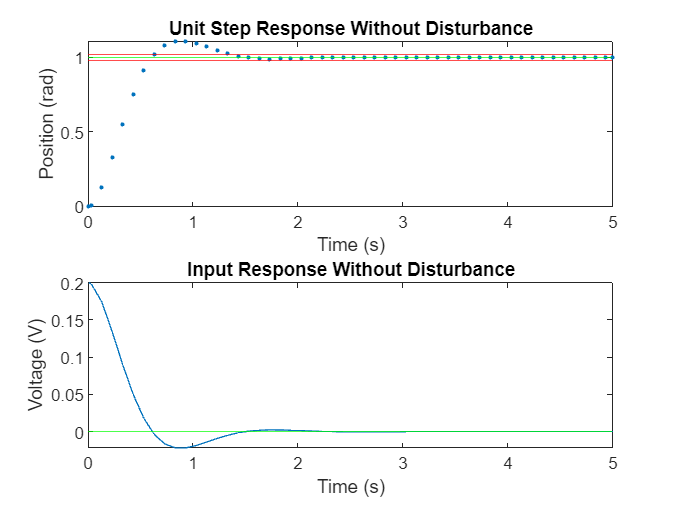

subplot(2, 1, 1)
plot(out1.Y.Time, out1.Y.Data, '.') % plot output response
yline(M, 'g')
yline(out1.Y.Data(end)*0.98, 'r')
yline(out1.Y.Data(end)*1.02, 'r')
title("Unit Step Response Without Disturbance")
xlabel("Time (s)")
ylabel("Position (rad)")

subplot(2, 1, 2)
plot(out1.U.Time, out1.U.Data) % plot input response
yline(0, 'g')
title("Input Response Without Disturbance")
xlabel("Time (s)")
ylabel("Voltage (V)")


fprintf("Final Error: %e rad", out1.E.Data(end)) % final error

Final Error: -1.638219e-07 rad

fprintf("Initial Input Voltage: %e V", out1.U.Data(1)) % initial input voltage

Initial Input Voltage: 2.000000e-01 V

fprintf("Final Input Voltage: %e V", out1.U.Data(end)) % final input voltage

Final Input Voltage: -3.276439e-08 V

#### 2a. Unit Step Response With Static Friction (Unit Step)

% coefficients
d = -0.01; 

out2 = sim('Closed_Loop_TF.slx', 5); % run the simulation

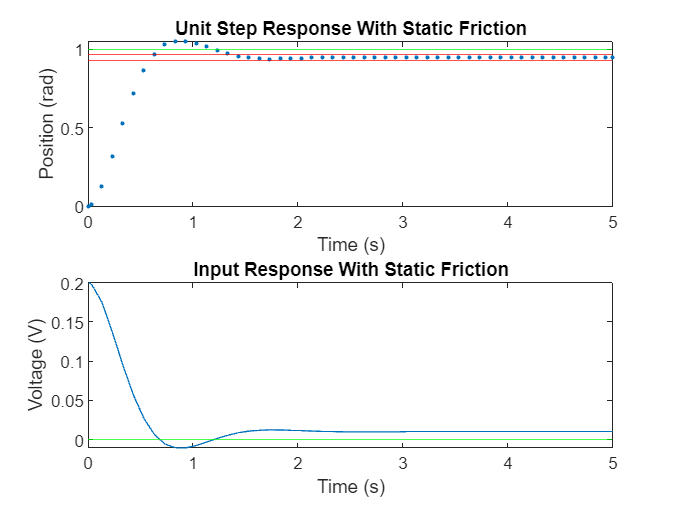

subplot(2, 1, 1)
% plot output response
plot(out2.Y.Time, out2.Y.Data, '.')
yline(M, 'g')
yline(out2.Y.Data(end)*0.98, 'r')
yline(out2.Y.Data(end)*1.02, 'r')
title("Unit Step Response With Static Friction")
xlabel("Time (s)")
ylabel("Position (rad)")

subplot(2, 1, 2)
% plot input response
plot(out2.U.Time, out2.U.Data)
yline(0, 'g')
title("Input Response With Static Friction")
xlabel("Time (s)")
ylabel("Voltage (V)")


fprintf("Final Error: %e rad", out2.E.Data(end)) % final error

Final Error: 4.999984e-02 rad

fprintf("Initial Input Voltage: %e V", out2.U.Data(1)) % initial input voltage

Initial Input Voltage: 2.000000e-01 V

fprintf("Final Input Voltage: %e V", out2.U.Data(end)) % final input voltage

Final Input Voltage: 9.999969e-03 V

#### 2b. Unit Step Response With Wind (Periodic Function)

% coefficients
d = -0.1; % disturbance amplitude
w = 10; % disturbance frequency

out3 = sim('Closed_Loop_TF_Sin.slx', 5); % run the simulation

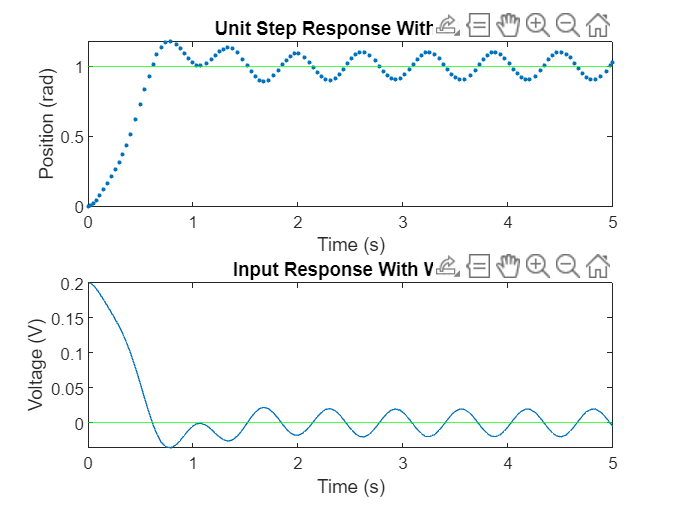

ss = mean(out3.Y.Data(end-18:end));

subplot(2, 1, 1)
% plot output response
plot(out3.Y.Time, out3.Y.Data, '.')
yline(M, 'g')
title("Unit Step Response With Wind")
xlabel("Time (s)")
ylabel("Position (rad)")

subplot(2, 1, 2)
% plot input response
plot(out3.U.Time, out3.U.Data)
yline(0, 'g')
title("Input Response With Wind")
xlabel("Time (s)")
ylabel("Voltage (V)")


fprintf("Final Error: %e rad", out3.E.Data(end)) % final error

Final Error: -2.830476e-02 rad

fprintf("Initial Input Voltage: %e V", out3.U.Data(1)) % initial input voltage

Initial Input Voltage: 2.000000e-01 V

fprintf("Final Input Voltage: %e V", out3.U.Data(end)) % final input voltage

Final Input Voltage: -5.660953e-03 V

#### 3. Unit Step Response With Noise (Unit Step)

% coefficients
d = -0.5; 

out4 = sim('Closed_Loop_TF_Noise.slx', 5);

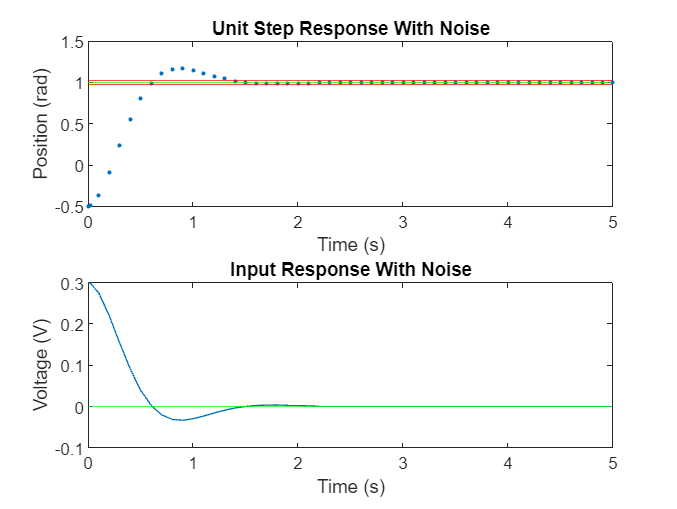

subplot(2, 1, 1)
% plot output response
plot(out4.Y.Time, out4.Y.Data, '.')
yline(M, 'g')
yline(out4.Y.Data(end)*0.98, 'r')
yline(out4.Y.Data(end)*1.02, 'r')
title("Unit Step Response With Noise")
xlabel("Time (s)")
ylabel("Position (rad)")

subplot(2, 1, 2)
% plot input response
plot(out4.U.Time, out4.U.Data)
yline(0, 'g')
title("Input Response With Noise")
xlabel("Time (s)")
ylabel("Voltage (V)")


fprintf("Final Error: %e rad", out4.E.Data(end)) % final error

Final Error: -2.457323e-07 rad

fprintf("Initial Input Voltage: %e V", out4.U.Data(1)) % initial input voltage

Initial Input Voltage: 3.000000e-01 V

fprintf("Final Input Voltage: %e V", out4.U.Data(end)) % final input voltage

Final Input Voltage: -4.914646e-08 V